# System Integration and Test Simulation

Configure a simulation that uses the following:

- Truth Locations - Field-collected ADSB data recorded with an RTL-SDR

- Detections and Sensor-based Tracks:

- Active radar (fusionRadarSensor)

- ADSB data (gpsSensor and ADSBReceiver)

- TrackFuser for C2 level tracks

- OSPA Metric, trackAssignmentMetrics, and errorMetrics for track accuracy analysis

close all force
clear

## Setup Scenario

Import truth location of aircraft and convert to trajectories for simulation

mapOrigin = [42.39423231362 -70.95934958874 0]; % Hard-coded this into radar2central and central2radar
load("C:\Users\pwilliam\OneDrive - MathWorks\Documents\SFTT\SFTTWorkshopPart2\Scenario\TrackingScenarioTruth.mat")

Scenario Creation includes configuring the Active Radar Sensor

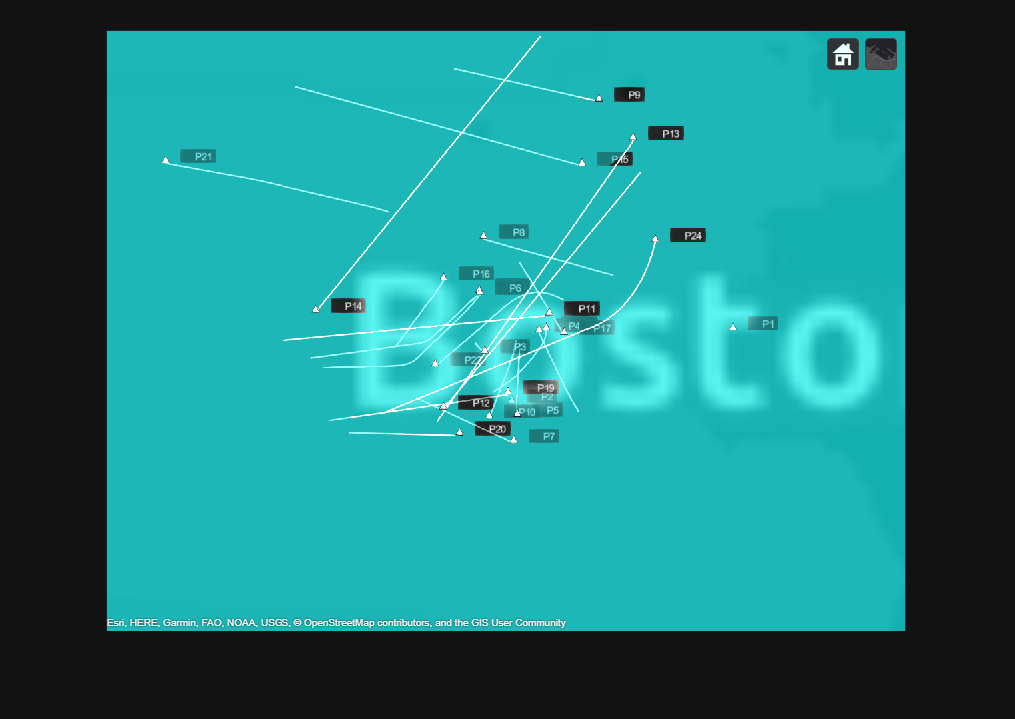

scenario = helperCreateScenario(tuningData,mapOrigin);
mapViewer = trackingGlobeViewer('ReferenceLocation',mapOrigin,'Basemap','streets-dark');
campos(mapViewer, mapOrigin + [0 -0.4 1e5]);
drawnow;
plotScenario(mapViewer,scenario);
snapshot(mapViewer);

## **Configure Tracker**

### Specify Aircraft Types

The first step in defining the tracker requires specifying the types of objects you want to track. In this example, these objects are passenger aircraft, general aviation aircraft, and helicopters. Use the [`trackerTargetSpec`](docid:fusion_ref#mw_d12c6e07-1099-4b7b-b09f-3be62d29245e) function to create a target specification for a passenger aircraft and observe the properties of the specification.

## **Step 1 - Create a Passenger Aircraft Target Specification using the trackerTargetSpec**

**Directions:**

Below, please create a variable 'passengerSpec' that holds the Passenger Aircraft Target Specification generated using 'trackerTargetSpec'. Use the "aerospace", "aircraft", and "passenger" inputs to specifiy the target specification.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% type "doc trackerTargetSpec" in the Command Window to find the documentation page for this function
% WRITE YOUR CODE BELOW THIS LINE:

% Define passengerSpec
passengerSpec = trackerTargetSpec("aerospace","aircraft","passenger");
disp(passengerSpec)

  PassengerAircraft with properties:

           MaxHorizontalSpeed: 250    m/s 
             MaxVerticalSpeed: 20     m/s 
    MaxHorizontalAcceleration: 10     m/s²
      MaxVerticalAcceleration: 1      m/s²



generalAviationSpec = trackerTargetSpec("aerospace","aircraft","general-aviation")

generalAviationSpec =   GeneralAviation with properties:

           MaxHorizontalSpeed: 150    m/s 
             MaxVerticalSpeed: 15     m/s 
    MaxHorizontalAcceleration: 1      m/s²
      MaxVerticalAcceleration: 5      m/s²


helicopterSpec = trackerTargetSpec("aerospace","aircraft","helicopter")

helicopterSpec =   Helicopter with properties:

           MaxHorizontalSpeed: 80    m/s 
             MaxVerticalSpeed: 10    m/s 
    MaxHorizontalAcceleration: 5     m/s²
      MaxVerticalAcceleration: 1     m/s²


activeRadarSpec = trackerSensorSpec("aerospace","radar","monostatic")

activeRadarSpec =   AerospaceMonostaticRadar with properties:

           MaxNumLooksPerUpdate: 30    
    MaxNumMeasurementsPerUpdate: 10    

    IsPlatformStationary: 1                  
        PlatformPosition: [0 0 0]         m  
     PlatformOrientation: [3⨯3 double]       
        MountingLocation: [0 0 0]         m  
          MountingAngles: [0 0 0]         deg

       HasElevation: 1                
       HasRangeRate: 1                
        FieldOfView: [60 20]       deg
        RangeLimits: [0 1e+05]     m  
    RangeRateLimits: [-500 500]    m/s

      AzimuthResolution: 1      deg
        RangeResolution: 100    m  
    ElevationResolution: 5      deg
    RangeRateResolution: 10     m/s

    DetectionProbability: 0.9      
          FalseAlarmRate: 1e-06    


targetSpec = {passengerSpec,generalAviationSpec,helicopterSpec};

towerPosition = mapOrigin; %[0 0 -50];
activeRadarSpec.MaxNumLooksPerUpdate = ceil(75*2/1.4); % Defines the number of looks in two seconds
activeRadarSpec.MaxNumMeasurementsPerUpdate = 20;
activeRadarSpec.PlatformPosition = [0 0 0];
activeRadarSpec.PlatformOrientation = eye(3);

activeRadarSpec = helperSyncSensor2spec(scenario.Platforms{1}.Sensors{1},activeRadarSpec);


### Configure Tracker to Use Target and Sensor Specifications

The last step in specifying the tracker is to configure it to use the heterogeneous target and sensor specifications you have defined.

tracker = multiSensorTargetTracker({passengerSpec,generalAviationSpec,helicopterSpec},activeRadarSpec,"jipda");
tracker.ConfirmationExistenceProbability = 0.95; % Increased from default because clutter density is high
release(tracker);

## Record Detection Data 

Optionally, generate recording of scenario.

This helps to speed up simulation that includes the trackers and fusers running on this detection data.

%sensorData = helperRecordSensorData(scenario);

Even faster, load the output from above. If further adjustments are made to scenario, "helperRecordSensorData" should be run to reflect those changes.

load('SensorData.mat');

Reset Scenario, Tracker, Viewer, and Transponders - Running helperRecordSensorData above leaves the simulation at the end time.

clear(mapViewer);
restart(scenario);
release(tracker);

Split dataset for easier parsing within simulation below.

trackerUpdateInterval = 1; % seconds
[activeRadarData] = helperSplitSensorData(sensorData,scenario.StopTime,trackerUpdateInterval);
savedPoses = helperSavePlatformPoses(scenario,trackerUpdateInterval);

## Configure Simulation

a = tic; % Time the simulation
detLog = [];
detBuffer = {};

% Preallocate variables for logging data for simulation:
truePoseGPSAll = cell(1, numel(activeRadarData));
radarTrackLog = cell(1, numel(activeRadarData));
trackError = cell(1, numel(activeRadarData));
truthError = cell(1, numel(activeRadarData));
plotPlatform(mapViewer,[scenario.Platforms{3:end}],TrajectoryMode="Full");

Configure track labels and colors

radarlabel = "  Radar";
radarclr = [255 255 17]/255;

## Instantiate Error Metrics and Assignment Metrics

## **Step 2- Instantiate the trackErrorMetrics to estimate the tracks' error compared to truth**

**Directions:**

Below, please create a variable 'errorMetrics' that holds the track error metrics generated using 'trackErrorMetrics'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% type "doc trackErrorMetrics" in the Command Window to find the documentation page for this function
% WRITE YOUR CODE BELOW THIS LINE:

% Define errorMetrics
errorMetrics = trackErrorMetrics;

assignmentMetrics = trackAssignmentMetrics(...
    'AssignmentDistance','posabserr',...
    'DivergenceDistance','posabserr',...
    'DivergenceThreshold',50,...
    'AssignmentThreshold',50);

## Run Scenario

This takes about 2 minutes to run.

for ind = 1:numel(activeRadarData)
    advance(scenario);

    % Plot Coverage of Radar
    covcon = coverageConfig(scenario);
    plotCoverage(mapViewer,covcon,"ECEF",Color=[0 1 0]) %Check coord sys

    % Gather true positions
    for i = 1:numel(scenario.Platforms)
        poseStruct = pose(scenario.Platforms{i},'CoordinateSystem','Geodetic');
        poseStruct.PlatformID = scenario.Platforms{i}.PlatformID;
        truePoseGPS(i) = poseStruct;
        truePoseNED(i) = poseStruct;
        truePoseNED(i).Position = lla2ned(truePoseGPS(i).Position,mapOrigin,'ellipsoid');
    end
    truePoseGPSAll{ind} = truePoseGPS;
    truePosePlot{ind} = platformPoses(scenario);

    % --- Plot Truth Locations ---
    plotPlatform(mapViewer, truePosePlot{ind}, 'ECEF');

    % --- Plot Detections ---
    plotActiveRadarData(mapViewer, activeRadarSpec, activeRadarData(ind));
    time = activeRadarData(ind).DetectionTime(1);

    % Instantiate variables for plotting - does not effect tracker
    % continuity
    radarTracks = objectTrack.empty;

    % --- Radar Processing ---        %radarTracks = tracker(activeRadarData(ind));

    % Use MEX version for speedup - outputs struct due to
    % codegeneration requirements
    radarTracks = trackingAlgorithm_mex({activeRadarData(ind)},targetSpec,activeRadarSpec);

    % Convert Struct output to objectTrack
    radarTracks = convertToObjectTrack(radarTracks);

    % --- Plotting ---
    labels = repmat(radarlabel, 1, numel(radarTracks));
    colors = repmat(radarclr, numel(radarTracks), 1);

    if ~isempty(radarTracks)
        plotTrack(mapViewer, radarTracks, ...
            'LabelStyle','Custom', ...
            "CustomLabel", repmat(radarlabel, 1, numel(radarTracks)), ...
            'Color', repmat(radarclr, numel(radarTracks), 1), ...
            'LineWidth', 3);
    end


    % --- Logging ---
    radarTrackLog{ind} = radarTracks;

    % --- Metrics ---
    [trackAssignmentSummary(ind), truthAssignmentSummary(ind)] = assignmentMetrics(radarTracks, truePoseNED);
    [assignedTrackIDs, assignedTruthIDs] = currentAssignment(assignmentMetrics);
    [posRMSE(ind), velRMSE(ind), posANEES(ind), velANEES(ind)] = errorMetrics(radarTracks, assignedTrackIDs, truePoseNED, assignedTruthIDs);
    trackError{ind} = cumulativeTrackMetrics(errorMetrics);
    truthError{ind} = cumulativeTruthMetrics(errorMetrics);
end
toc(a)

Elapsed time is 132.829685 seconds.


Take Snapshot of Viewer

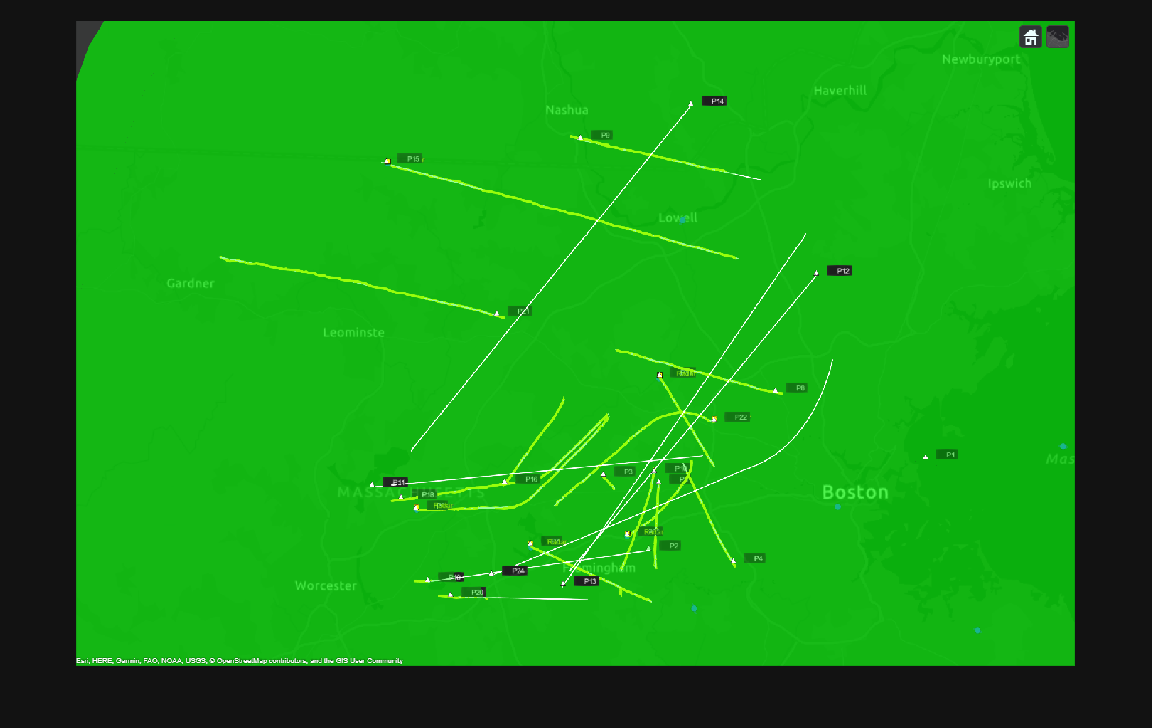

snapshot(mapViewer);

## Collect Error Metrics

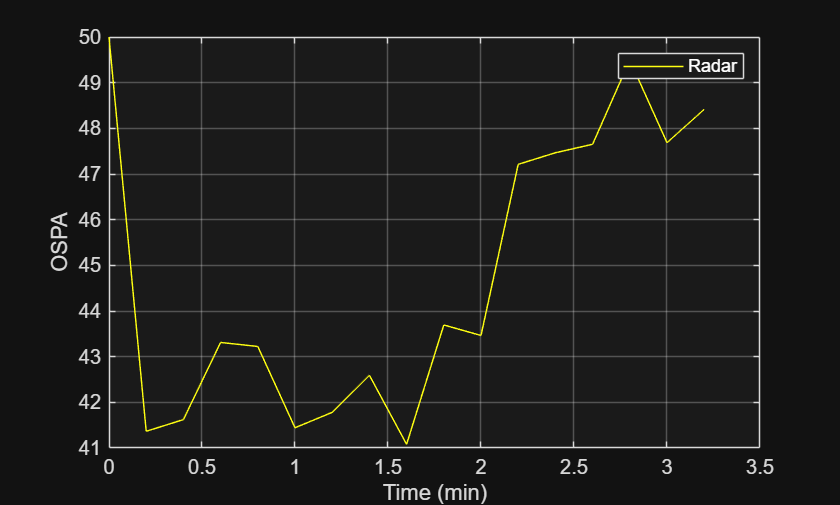

ospa = trackOSPAMetric('CutoffDistance',50);
radarospa = zeros(ceil(numel(radarTrackLog)/12),1);

% Compute radar tracker OSPA
for i=1:12:numel(radarTrackLog)
    tracks = radarTrackLog{i};
    %[truths.Position, ~,truths.Velocity] = lookupPose(flightRoute, i-1,'ECEF');
    truths = truePoseGPSAll{i}; % Consider omitting the sensor platforms
    for j = 1:length(truths)
        pos = truths(j).Position;
        truths(j).Position = lla2ned(pos,mapOrigin,'ellipsoid');
    end
    radarospa(i) = ospa(tracks, truths);
end


% Plot OSPA
figure
hold on
plot((0:12:(numel(radarTrackLog)-1))/60, radarospa(1:12:end), "Color",radarclr);

l=legend('Radar');
l.Color = [0.1 0.1 0.1];
l.TextColor = [ 1 1 1];
xlabel('Time (min)')
ylabel('OSPA')
ax = gca;
grid on;
box on;
ax.Color = [0.1 0.1 0.1];
ax.GridColor = [1 1 1];

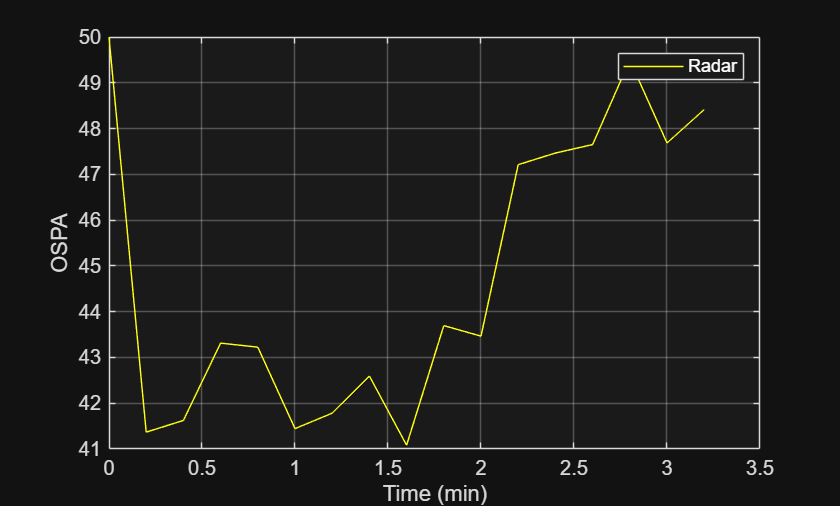

% Plot OSPA Separately
figure
plot((0:12:(numel(radarTrackLog)-1))/60, radarospa(1:12:end), "Color",radarclr);
l=legend('Radar');
ylabel('OSPA')

l.Color = [0.1 0.1 0.1]; l2.Color = [0.1 0.1 0.1]; l3.Color = [0.1 0.1 0.1];
l.TextColor = [ 1 1 1]; l2.TextColor = [ 1 1 1]; l3.TextColor = [ 1 1 1];
xlabel('Time (min)')
%ylabel('OSPA')
ax = gca;
grid on;
box on;
ax.Color = [0.1 0.1 0.1];
ax.GridColor = [1 1 1];

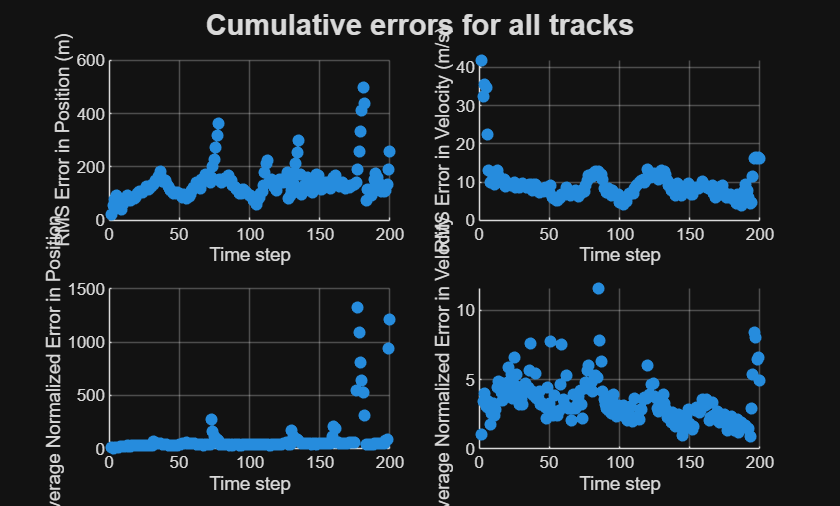

%% Plot RMS values
figure;
timeVec = 1:length(posRMSE);
subplot(2,2,1)
scatter(timeVec,posRMSE,'filled');
xlabel('Time step');
ylabel('RMS Error in Position (m)');
grid('on');

subplot(2,2,2)
scatter(timeVec,velRMSE,'filled');
xlabel('Time step');
ylabel('RMS Error in Velocity (m/s)');
grid('on');

subplot(2,2,3)
scatter(timeVec,posANEES,'filled');
xlabel('Time step');
ylabel('Average Normalized Error in Position');
grid('on');

subplot(2,2,4)
scatter(timeVec,velANEES,'filled');
xlabel('Time step');
ylabel('Average Normalized Error in Velocity');
grid('on');

sgtitle('Cumulative errors for all tracks','FontWeight','bold');

## Helper Functions

**helperCreateScenario**

function scenario = helperCreateScenario(tuningData,mapOrigin)
scenarioDuration = 200; % s
scenario = trackingScenario(UpdateRate=1,StopTime=scenarioDuration,IsEarthCentered=true);
radarTower = platform(scenario, Position=mapOrigin);

rpm = 20;
beamwidthAz = 360; % degrees
fov = [beamwidthAz; 15]; % narrower azimuth FoV
%scanrate = rpm * 360 / 60; % deg/s
updaterate = 1; % Hz, or match scan revisit rate
activeRadar = fusionRadarSensor(1,"No Scanning", ...
    UpdateRate=updaterate, ...
    FieldOfView=fov, ...
    AzimuthResolution=1.4, ...
    ReferenceRange=111e3, ...
    ReferenceRCS=0, ...
    RangeResolution=135, ...
    HasElevation=true, ...
    HasNoise=true, ...
    HasFalseAlarms=true, ...
    FalseAlarmRate=1e-7,...
    HasRangeRate=true, ...
    RangeRateLimits=[-600 600], ...
    MountingLocation=[0 0 -15], ...
    MountingAngles=[0 0 0], ...
    HasINS=true, ...
    DetectionCoordinates="Sensor spherical");


% Mount radar at the top of the tower
radarTower.Sensors = activeRadar;

% Set mechanical elevation scan to begin at 2 degrees above the horizon
elFov = fov(2);
activeRadar.FieldOfView(2) = elFov+1e-3;

% Place ADSB Tower
applehillPos = [42.300498, -71.349157 0]; % LLA- isEarthCentered=true
ADSBTower = platform(scenario, Position=applehillPos); %[-5000 -3000 -50]

% Create Platforms for each Aircraft in TuningData
for i = 1:numel(tuningData)

    % Geo Trajectory - isEarthCentered = true
    Pos = tuningData{i}.Position;
    time = seconds(tuningData{i}.Time);

    % Find indices where time is within the scene duration
    validIdx = time <= scenarioDuration;

    % Truncate time and position vectors
    truncatedTime = time(validIdx);
    truncatedPos = Pos(validIdx, :);

    % Generate Trajectory
    traj = geoTrajectory(truncatedPos,truncatedTime);

    % Create Platform that follows above trajectory
    platform(scenario,Trajectory=traj);
end
end

**helperRecordSensorData**

function sensorData = helperRecordSensorData(scenario) %#ok<DEFNU>
if isa(scenario,"trackingScenarioRecording")
    recording = scenario.RecordedData; % We only need the struct
elseif isa(scenario,"struct")
    recording = scenario;
elseif isa(scenario,"trackingScenario") || isa(scenario,"radarScenario")
    seed = 2024; % Change this value if you want a different random number generator seed.
    disp("Recording the scenario to get sensor data. This may take several minutes.");
    recording = record(scenario,"Rotmat",IncludeSensors=true,RecordingFormat="struct",InitialSeed=seed);
else
    error("This example utility function can only be used with a trackingScenario a trackingScenarioRecording");
end

if ~isfield(recording,"SensorConfigurations") || ~isfield(recording,"Detections")
    error("Scenario recording must contain sensor configurations and detections to record sensor data");
end
% Assume all steps have the same sensors.
sensors = recording(1).SensorConfigurations;
detBuffer = vertcat(recording.Detections);
for i = 1:numel(recording)
    for j = 1:numel(recording(i).SensorConfigurations)
        recording(i).SensorConfigurations(j).Time = recording(i).SimulationTime;
    end
end
configBuffer = reshape([recording.SensorConfigurations],[],1);
sensorData = cell(1,numel(sensors));
for k = 1:numel(sensors)
    sensor = sensors(k);
    sensorIdx = sensor.SensorIndex;
    sensorMountingAngles =  eye(3); %rotmat(recording(1).CoverageConfig(k).Orientation,"frame");

    detSensorIndex = cellfun(@(x)x.SensorIndex,detBuffer);
    dets = detBuffer(detSensorIndex == sensorIdx);

    cfgSensorIndex = arrayfun(@(x)x.SensorIndex, configBuffer);
    cfgs = configBuffer(cfgSensorIndex == sensorIdx);
    if sensor.MeasurementParameters(1).HasRange
        sensorData{k} = recordMonostaticData(sensorMountingAngles, dets, cfgs);
    else
        %sensorData{k} = recordESMData(sensorMountingAngles, dets, cfgs);
        disp('no ESM sensor, not recording')
    end
end
end

**recordMonostaticData**

function activeRadarData = recordMonostaticData(sensorMountingAngles, detections, cfgs)
% Reported config information
lookMountRot = cell(numel(cfgs),1);
for i = 1:numel(cfgs)
    if cfgs(i).MeasurementParameters(1).IsParentToChild
        lookMountRot{i} = cfgs(i).MeasurementParameters(1).Orientation;
    else
        lookMountRot{i} = cfgs(i).MeasurementParameters(1).Orientation';
    end
end
beamRot = cellfun(@(x)x*sensorMountingAngles',lookMountRot,UniformOutput=false);
ypr = cellfun(@(x)fusion.internal.frames.rotmat2ypr(x,"degrees"),beamRot,UniformOutput=false);
lookTime = arrayfun(@(x)x.Time,cfgs);
lookAzimuth = cellfun(@(x)x(1),ypr);
lookElevation = cellfun(@(x)-x(2),ypr);

% Reported measurement information
detectionTime = cellfun(@(x)x.Time,detections);
azimuth = cellfun(@(x)x.Measurement(1),detections);
elevation = cellfun(@(x)x.Measurement(2),detections);
range = cellfun(@(x)x.Measurement(3),detections);
rangeRate = cellfun(@(x)x.Measurement(4),detections);
azimuthAccuracy =  cellfun(@(x)x.MeasurementNoise(1,1),detections);
elevationAccuracy =  cellfun(@(x)x.MeasurementNoise(2,2),detections);
rangeAccuracy =  cellfun(@(x)x.MeasurementNoise(3,3),detections);
rangeRateAccuracy =  cellfun(@(x)x.MeasurementNoise(4,4),detections);

activeRadarData = struct(LookTime=lookTime(:)',LookAzimuth=lookAzimuth(:)', ...
    LookElevation=lookElevation(:)', DetectionTime=detectionTime(:)', ...
    Azimuth=azimuth(:)',Elevation=elevation(:)', Range=range(:)', ...
    RangeRate=rangeRate(:)',AzimuthAccuracy=sqrt(azimuthAccuracy(:)'), ...
    ElevationAccuracy=sqrt(elevationAccuracy(:)'),RangeAccuracy=sqrt(rangeAccuracy(:)'), ...
    RangeRateAccuracy=sqrt(rangeRateAccuracy(:)'));
end

`helperSyncSensor2spec` - A helper to synchronize sensor properties to the sensor specification

function spec = helperSyncSensor2spec(sensor,spec)
if isa(sensor,'fusionRadarSensor') && strcmpi(sensor.DetectionMode,'monostatic')
    spec = syncRadar2spec(sensor,spec);
elseif isa(sensor,'fusionRadarSensor') && strcmpi(sensor.DetectionMode,'esm')
    spec = syncESM2spec(sensor,spec);
end
end

**syncRadar2spec**

function spec = syncRadar2spec(sensor,spec)
spec.MountingLocation = sensor.MountingLocation;
spec.MountingAngles = sensor.MountingAngles;
spec.HasElevation = sensor.HasElevation;
spec.HasRangeRate = sensor.HasRangeRate;
spec.FieldOfView = sensor.FieldOfView;
spec.RangeLimits = sensor.RangeLimits;
spec.RangeRateLimits = sensor.RangeRateLimits;
spec.AzimuthResolution = sensor.AzimuthResolution;
spec.RangeResolution = sensor.RangeResolution;
spec.ElevationResolution = sensor.ElevationResolution;
spec.RangeRateResolution = sensor.RangeRateResolution;
spec.DetectionProbability = sensor.DetectionProbability;
spec.FalseAlarmRate = sensor.FalseAlarmRate;
end

function spec = syncESM2spec(sensor,spec)
spec.MountingLocation = sensor.MountingLocation;
spec.MountingAngles = sensor.MountingAngles;
spec.HasElevation = sensor.HasElevation;
spec.FieldOfView = sensor.FieldOfView;
spec.AzimuthResolution = sensor.AzimuthResolution;
spec.ElevationResolution = sensor.ElevationResolution;
spec.DetectionProbability = sensor.DetectionProbability;
spec.FalseAlarmRate = sensor.FalseAlarmRate;
end


**helperSplitSensorData** - A helper to split recorded sensor data to the tracker update interval

function varargout=helperSplitSensorData(sensorData,stopTime,trackerInterval)
varargout = cell(1,nargout);
if iscell(sensorData)
    varargout = cellfun(@(s) splitOneSensorData(s,stopTime,trackerInterval), sensorData, UniformOutput=false);
else
    varargout{1} = splitOneSensorData(sensorData,stopTime,trackerInterval);
end
end

**splitOneSensorData**

function data=splitOneSensorData(sensorData,stopTime,trackerInterval)
frameTime = 0;
ind = 1;
numFrames = ceil(stopTime/trackerInterval);
data = repmat(sensorData,numFrames,1);
while frameTime < stopTime
    withinInterval = sensorData.LookTime >= frameTime & sensorData.LookTime < frameTime+trackerInterval;
    data(ind).LookTime = sensorData.LookTime(withinInterval);
    data(ind).LookAzimuth = sensorData.LookAzimuth(withinInterval);
    data(ind).LookElevation = sensorData.LookElevation(withinInterval);
    withinInterval = sensorData.DetectionTime >=frameTime & sensorData.DetectionTime < frameTime+trackerInterval;
    data(ind).DetectionTime = sensorData.DetectionTime(withinInterval);
    if isfield(sensorData,"Azimuth")
        data(ind).Azimuth = sensorData.Azimuth(1,withinInterval);
        data(ind).AzimuthAccuracy = sensorData.AzimuthAccuracy(1,withinInterval);
    end
    if isfield(sensorData,"Elevation")
        data(ind).Elevation = sensorData.Elevation(1,withinInterval);
        data(ind).ElevationAccuracy = sensorData.ElevationAccuracy(1,withinInterval);
    end
    if isfield(sensorData,"Range")
        data(ind).Range = sensorData.Range(1,withinInterval);
        data(ind).RangeAccuracy = sensorData.RangeAccuracy(1,withinInterval);
    end
    if isfield(sensorData,"RangeRate")
        data(ind).RangeRate = sensorData.RangeRate(1,withinInterval);
        data(ind).RangeRateAccuracy = sensorData.RangeRateAccuracy(1,withinInterval);
    end
    if isfield(sensorData,"TargetIndex")
        data(ind).TargetIndex = sensorData.TargetIndex(1,withinInterval);
    end
    frameTime = frameTime + trackerInterval;
    ind = ind + 1;
end
end


**helperSavePlatformPoses** - Record platform poses at tracker update timestamps

function platformPoses = helperSavePlatformPoses(scenario,trackerInterval)
endind = ceil(scenario.StopTime/trackerInterval);
samplePose = struct(PlatformID=1,ClassID=0,Position=zeros(1,3),Velocity=zeros(1,3),Acceleration=zeros(1,3),Orientation=eye(3),AngularVelocity=zeros(1,3));
platformPoses = repmat(samplePose,numel(scenario.Platforms),endind);
sampleTimes = trackerInterval*(1:endind);

for p = 1:numel(scenario.Platforms)
    thisPlatform = scenario.Platforms{p};
    trajectory = thisPlatform.Trajectory;
    if isa(trajectory,"waypointTrajectory")
        [position,orientation,velocity,acceleration,angularVelocity] = lookupPose(trajectory,sampleTimes);
        orientation = rotmat(orientation,"frame");
        for i = 1:endind
            platformPoses(p,i) = struct(PlatformID=thisPlatform.PlatformID,ClassID=thisPlatform.ClassID, ...
                Position=position(i,:),Velocity=velocity(i,:),Acceleration=acceleration(i,:), ...
                Orientation=orientation(:,:,i),AngularVelocity=angularVelocity(i,:));
        end
    else % Assumes that non waypointTrajectory means stationary object
        platformPoses(p,:) = repmat(struct(PlatformID=thisPlatform.PlatformID,ClassID=thisPlatform.ClassID, ...
            Position=thisPlatform.Position,Velocity=zeros(1,3),Acceleration=zeros(1,3),Orientation=thisPlatform.Orientation, ...
            AngularVelocity=zeros(1,3)),1,endind);
    end
end
end

**syncTrack**

function tr1 = syncTrack(tr1,tr2)
% A function to syncs properties of one track with another except the
% "State" and "StateCovariance" property
props = {...
    'TrackID', ...
    'BranchID', ...
    'SourceIndex', ...
    'UpdateTime', ...
    'Age', ...
    'StateParameters', ...
    'ObjectClassID', ...
    'IsConfirmed', ...
    'IsCoasted', ...
    'IsSelfReported', ...
    'ObjectAttributes'}; % Omit: 'TrackLogicState', ...
for i = 1:numel(props)
    tr1.(props{i}) = tr2.(props{i});
end
end

**convertToObjectTrack**

function tracksObj = convertToObjectTrack(tracksStruct)
tracksObj = repmat(objectTrack, numel(tracksStruct), 1);
for i = 1:numel(tracksStruct)
    tracksObj(i) = objectTrack( ...
        'TrackID', tracksStruct(i).TrackID, ...
        'BranchID', tracksStruct(i).BranchID, ...
        'SourceIndex', tracksStruct(i).SourceIndex, ...
        'UpdateTime', tracksStruct(i).UpdateTime, ...
        'Age', tracksStruct(i).Age, ...
        'State', tracksStruct(i).State, ...
        'StateCovariance', tracksStruct(i).StateCovariance, ...
        'StateParameters', tracksStruct(i).StateParameters, ...
        'ObjectClassID', tracksStruct(i).ObjectClassID, ...
        'ObjectClassProbabilities', tracksStruct(i).ObjectClassProbabilities, ...
        'TrackLogic', tracksStruct(i).TrackLogic, ...
        'TrackLogicState', tracksStruct(i).TrackLogicState, ...
        'IsConfirmed', tracksStruct(i).IsConfirmed, ...
        'IsCoasted', tracksStruct(i).IsCoasted, ...
        'IsSelfReported', tracksStruct(i).IsSelfReported, ...
        'ObjectAttributes', tracksStruct(i).ObjectAttributes ...
        );
end
end